# Case Study: Pellet Smoker


clc; close all; clear all;

## Variables

syms Tf Tc      % temperatures (C)
syms mp;        % pellet mass (g)
syms up;        % pellet feed rate (g/s)
syms uf;        % fan command [0, 1]
syms Tamb;      % ambient temp (C)
syms Cf Cc;     % heat capacities (J/C)
syms kf;        % thermal coupling firepot/chamber (W/C)
syms kfa kca;   % losses to ambient (W/C)
syms gamma      % heating power factor (W/(g/s*fan))

x = [Tf; Tc; mp];
tester = [Cf Cc kf]

$$tester = \left(\begin{array}{ccc} \mathrm{Cf} & \mathrm{Cc} & \mathrm{kf} \end{array}\right)$$

## 2.4 Equilibrium Points

Ae = [-(kf+kfa)/Cf   kf/Cf           0;
    kf/Cc           -(kf+kca)/Cc    0;
    0               0               0];

Be = [gamma*uf/Cf    gamma*up/Cf;
    0               0;
    -1              0];
Wc = [Be Ae*Be Ae^2*Be];
RankWc = rank(Wc)

RankWc = 3

## 2.6 Numerical Specification

A = double(subs(Ae, [Cf Cc kf kfa kca], [500 2500 150 20 25]));
B = double(subs(Be, [gamma up uf Cf], [1000 0.4 0.6 500]));
C = [0 1 0];
D = 0;

## 2.7 Design Challenges

## 2.7.1 Step response

up = @(t) t>0

up = function_handle with value:
    @(t)t>0


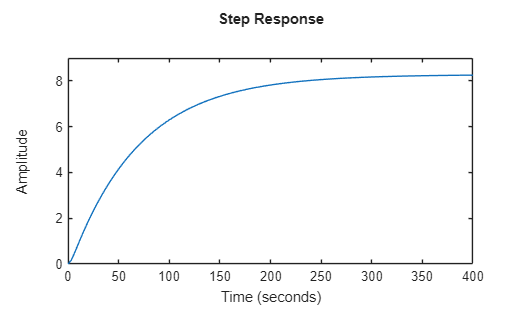

sys71 = ss(A, B, C, D);
step(sys71(:,2))

### 2.7.2 Integral Action

A_tilde = [A zeros(3,1);
           C 0]

A_tilde =    -0.3400    0.3000         0         0
    0.0600   -0.0700         0         0
         0         0         0         0
         0    1.0000         0         0


K = zeros(2, 4)

K =      0     0     0     0
     0     0     0     0


Kr = [0;0;0;0]

Kr =      0
     0
     0
     0


B_tilde = [B; zeros(1,2)]

B_tilde =     1.2000    0.8000
         0         0
   -1.0000         0
         0         0


C_tilde = [C 0]

C_tilde =      0     1     0     0


D_tilde = 0;


### 2.7.3 Disturbance Rejection

### 2.7.4 Observer Design

### 2.7.5 Optimizing for changing setpoints

### 2.7.6 Robustness

### 2.7.7 EC Advanced Control Synthesis